clear
num_c = 10;  % number of cars

% Initial Conditions
% Note: The index of the car corresponds to the order of the car. (Ex: Car 1
% is in the first element of the vector)
pos_0 = linspace(200, 0, num_c); % Initial position of cars.
vel_0 = zeros(1,num_c); % Initial velocity of cars.
acc_0 = zeros(1,num_c); % Inital acceleration of cars.

% Characteristic of cars and road.
lengths = ones(1,num_c)*5; % Length of cars.
gamma = 0.6; % Speed difference sensitivity.
x_destination = 2000; % Destination.
maxLane = 1;
b_safe = 2;
delta_a = 0.1;
a_bias = 0.3;

% Parameters for Numerical Integration
tstep = .01;
t_final = 100;
numsteps = round(t_final/tstep);

% Default initialize an array and set parameters for the vehicles.
vehiclesInOrder(1:num_c) = Vehicle();
for i = 1:num_c
    vehiclesInOrder(i) = Vehicle(i, pos_0(i), vel_0(i), acc_0(i), 1, lengths(i), false);
end

% Create array to store time, position, velocity, acceleration, and gap.
tvals = linspace(0, t_final, numsteps);
xvals = zeros(numsteps, num_c);
vvals = zeros(numsteps, num_c);
avals = zeros(numsteps, num_c);
gvals = zeros(numsteps, num_c);
lanevals = zeros(numsteps, num_c);


for t = 1:numsteps
    for i = num_c:-1:1 % Loop through the car starting with the last car.
        if ~vehiclesInOrder(i).isVirtual
            laneNum = vehiclesInOrder(i).lane;
            [v_l, s, ~, ~] = Vehicle.findGaps(vehiclesInOrder, i, laneNum, x_destination);

            % Compute gap and state variables.
            newstate = vehiclesInOrder(i).timestep(s, v_l, tstep, gamma);
            v_num = vehiclesInOrder(i).number;
            gvals(t, v_num) = s;
            xvals(t, v_num) = newstate(1);
            vvals(t, v_num) = newstate(2);
            avals(t, v_num) = newstate(3);
            lanevals(t, v_num) = vehiclesInOrder(i).lane;
        end
    end
    vehiclesInOrder = Vehicle.sortCars(vehiclesInOrder);
end

xvals = xvals(:,1:num_c);
vvals = vvals(:,1:num_c);
avals = avals(:,1:num_c);
gvals = gvals(:,1:num_c);

% Build colormap 
cmap = (1/256) .*[0, 0, 0;
        105, 105, 105;
        211, 211, 211;
        85, 107, 47;
        139, 69, 19;
        34, 139, 34;
        72, 61, 139;
        184, 134, 11;
        0, 139, 139;
        70, 130, 180;
        0, 0, 128;
        154, 205, 50;
        143, 188, 143;
        139, 0, 139;
        176, 48, 96;
        255, 69, 0;
        255, 215, 0;
        124, 252, 0;
        138, 43, 226;
        0, 255, 127;
        220, 20, 60;
        0, 255, 255;
        0, 0, 255;
        255, 0, 255;
        30, 144, 255;
        240, 230, 140;
        144, 238, 144;
        255, 20, 147;
        255, 160, 122;
        238, 130, 238];
colorspec = num2cell(cmap,2);

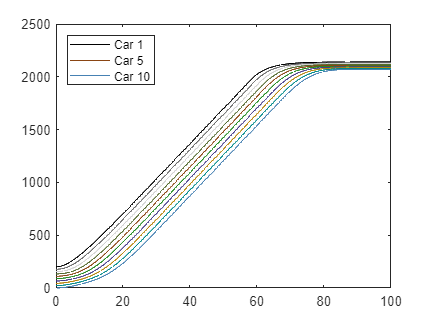

% Graph position versus time. 
for i = 1:num_c 
    h(i) = plot(tvals, xvals(:,i), 'Color', colorspec{i});
    hold on;
end
legend([h(1) h(5) h(10)], 'Car 1', 'Car 5', 'Car 10', 'Location', 'northwest');
xlim([0 t_final]);
hold off;

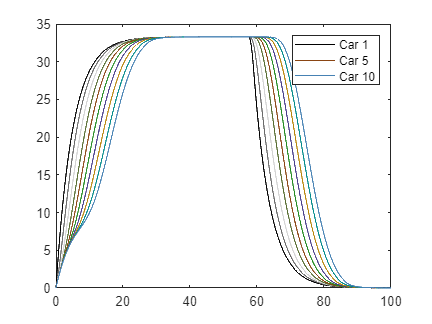

% Graph velocity versus time.
for i = 1:num_c 
    h(i) = plot(tvals, vvals(:,i), 'Color', colorspec{i});
    hold on;
end
legend([h(1) h(5) h(10)], 'Car 1', 'Car 5', 'Car 10');
xlim([0 t_final]);
hold off;

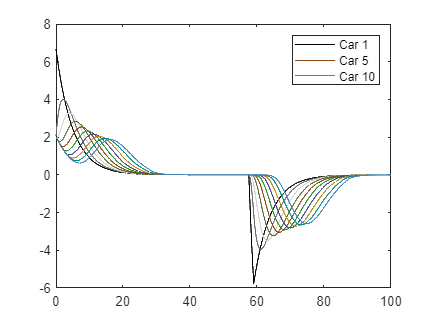

% Graph acceleration versus time.
for i = 1:num_c 
    h(i) = plot(tvals, avals(:,i), 'Color', colorspec{i});
    hold on;
end
legend([h(1) h(5) h(10)], 'Car 1', 'Car 5', 'Car 10');
xlim([0 t_final]);
hold off;

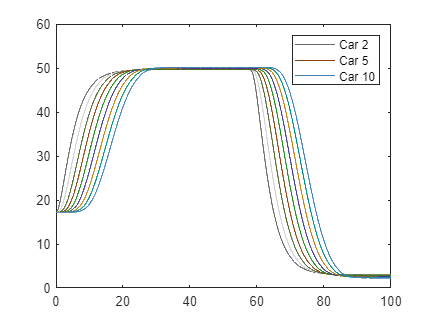

% Graph gap versus time.
for i = 2:num_c 
    h(i) = plot(tvals, gvals(:,i), 'Color', colorspec{i});
    hold on;
end
legend([h(2) h(5) h(10)], 'Car 2', 'Car 5', 'Car 10');
xlim([0 t_final]);
hold off